# Quickstart: Accessing Neuropixels electrophysiology data from the Allen Brain Observatory

This quickstart example demonstrates access and basic analysis of the Visual Coding Neuropixels dataset [1] from the Allen Brain Observatory [2].

### Accessing the Visual Coding Neuropixels Dataset

availSessions = bot.fetchSessions('ephys');
availProbes = bot.fetchProbes();
availChannels = bot.fetchChannels();
availUnits = bot.fetchUnits();

There are 58 available sessions in the Visual Coding - Neuropixels dataset


#### Inspect Available Sessions 

head(availSessions)

ans = 8×15 table
       id        unit_count    channel_count    probe_count        session_type         age_in_days    fail_eye_tracking    sex                      full_genotype                                                                      ephys_structure_acronyms                                                    isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _____________________    ___________    _________________    ___    _________________________________________________

#### Select Sessions of Interest

% select sessions with female subjects
filteredSessions = availSessions(availSessions.sex == "F",:);
% select sessions with wild-type subjects
filteredSessions = filteredSessions(filteredSessions.full_genotype == "wt/wt",:);
% select sessions designed to investigate functional connectivity
filteredSessions = filteredSessions(filteredSessions.session_type == "functional_connectivity",:); 
disp(filteredSessions)

       id        unit_count    channel_count    probe_count         session_type          age_in_days    fail_eye_tracking    sex    full_genotype                                              ephys_structure_acronyms                                              isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _______________________    ___________    _________________    ___    _____________    _______________________________________________________________________________

#### Create Session Object 

sessionUnderStudy = bot.session(filteredSessions(1,:)); 
sessionUnderStudy.info

ans = struct with fields:
                          id: 819186360
                  unit_count: 531
               channel_count: 1696
                 probe_count: 5
                session_type: functional_connectivity
                 age_in_days: 128
           fail_eye_tracking: 0
                         sex: F
               full_genotype: "wt/wt"
    ephys_structure_acronyms: "APN; CA1; CA3; DG; HPF; LGd; LP; MB; NOT; POL; SCig; SCiw; SCop; SUB; VISam; VISl; VISpm; VISrl"
           isi_experiment_id: 809373390
         date_of_acquisition: 08-Feb-2019 09:02:25
                 specimen_id: 800249587
                    specimen: [1×1 struct]
            well_known_files: [1×1 struct]


#### Inspect Session Object Properties

disp(sessionUnderStudy)

  ephyssession with properties:

                              info: [1×1 struct]
                                id: 819186360
                       linkedFiles: [2×1 table]

   Info Derived Values
                structure_acronyms: [1×18 string]

   Linked Items
                            probes: [5×23 table]
                          channels: [1696×29 table]
                             units: [531×51 table]

   Linked Item Derived Values


       channel_structure_intervals: [34×2 table]
         structurewise_unit_counts: [15×2 table]

   Linked File Values ('SessNWB')
      inter_presentation_intervals: '[on demand]'
                     invalid_times: '[on demand]'
                    mean_waveforms: '[on demand]'
    optogenetic_stimulation_epochs: '[on demand]'
                        pupil_data: '[on demand]'
               pupil_data_detailed: '[on demand]'
                      rig_metadata: '[on demand]'
                     running_speed: '[on demand]'
                session_start_time: '[on demand]'
                  spike_amplitudes: '[on demand]'
                       spike_times: '[on demand]'
               stimulus_conditions: '[on demand]'
                   stimulus_epochs: '[on demand]'
                    stimulus_names: '[on demand]'
            stimulus_presentations: '[on demand]'

   Linked File Values ('StimTemplatesGroup')
                stimulus_templates: '[on demand]'



#### Group Analysis of Session Units

unitsTable = sessionUnderStudy.units;
head(unitsTable)
summary(unitsTable(:,"firing_rate"));
histogram(unitsTable.firing_rate);
ylabel('Firing Rate (Hz)');

ans = 8×51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id         session_type          ephys_structure_acronym     L_ratio      age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio    

title("Units from Session ID " + sessionUnderStudy.id);

Description:  epoch_name_quality_metrics: complete_session - epoch_name_waveform_metrics: complete_session - quality: good - type: EPhys - published_at: 03-Oct-2019 - has_nwb: true 

Variables:

    firing_rate: 531×1 double

        Values:

            Min       0.096779
            Median      5.4277
            Max         46.996



### Examining Stimuli Presentations

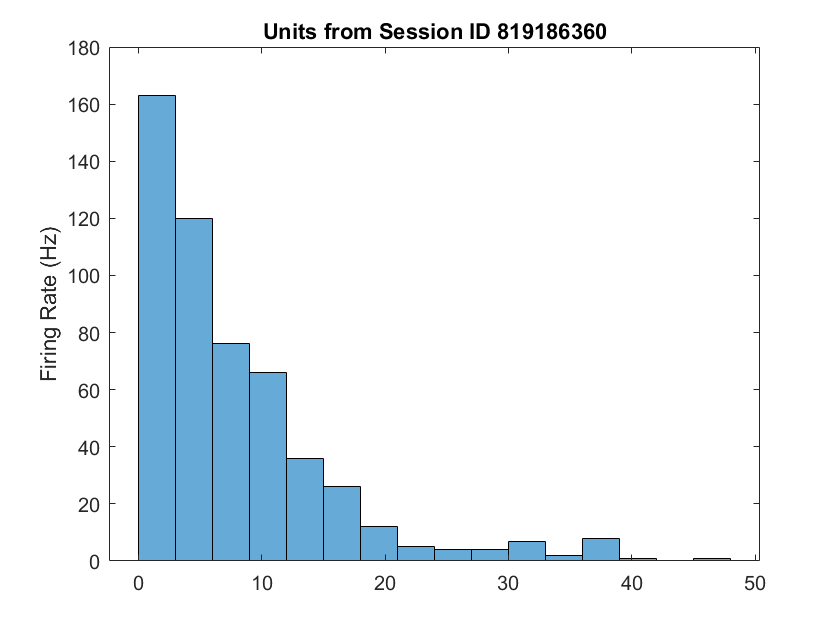

% Filter
sessions = availSessions(~availSessions.fail_eye_tracking, :);


% Select sessions on wild-type animals
sessions = sessions(sessions.full_genotype == "wt/wt", :)

% Obtain a single experimental session
sess = bot.session(sessions(1, :));

% Get a full table of individual stimulus presentations
stimuli = sess.stimulus_presentations;
head(stimuli)

### Examining data from a single unit

units = sess.units;
% Units from the primary visual cortex ('VISp') can now be filtered out
units = units(units.ephys_structure_acronym == 'VISp', :)
% Obtain a `unit` object for the first unit
unit = bot.unit(units(1, :))
fieldnames(unit.info)

## References

[1] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 